# Test Scrip

# Page 1

close all
clear
clc

coef(1,:,1) = [1,0,1]

coef =      1     0     1


coef(2,:,1) = [1,0,0.64]

coef =     1.0000         0    1.0000
    1.0000         0    0.6400


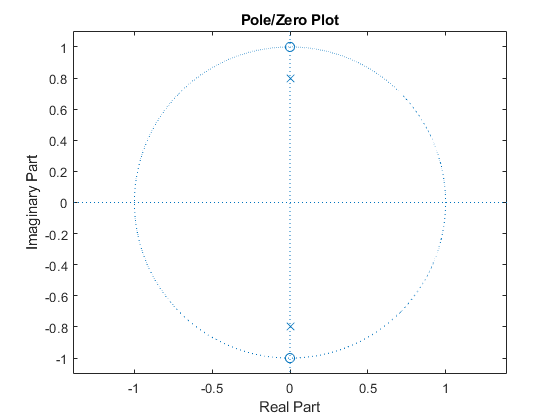

Orignal Gain: 1.2195
K value: 0.82


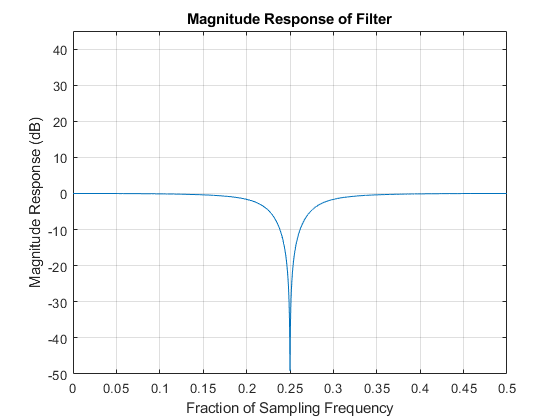

DigitalPloter(coef,0)

# Page2

**********************
Section # 1
Numerator coefficients 1 -2 1
Denominator coefficients 1 1.1894 0.50441
______________________
**********************
**********************
Section # 2
Numerator coefficients 1 -2 1
Denominator coefficients 1 0.6207 0.81443
______________________
**********************


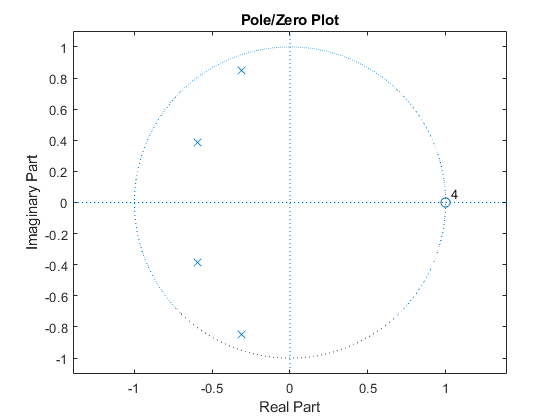

Orignal Gain: 53.5576
K value: 0.059044


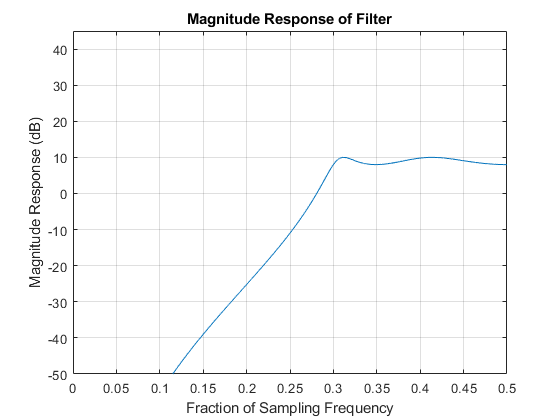

close all
clear
clc

digi = HWSolver("Chebyshev","High",10,2,25,300,220,1000);

digi.Filter.order

ans = 4

digi.Filter.Display

______________________
Chebyshev Section 1
     w0  = 5.8481 rad/sec
     Q  = 0.92945
     (or angle  = 57.4556 degrees)
______________________
**********************
______________________
Chebyshev Section 2
     w0  = 2.8565 rad/sec
     Q  = 4.5939
     (or angle  = 83.7515 degrees)
______________________


digi.zpoles

ans =   -0.5947 + 0.3883i  -0.3103 + 0.8474i


coef = digi.coef;
num = coef(1,:,1);
den = coef(2,:,1);

if not(length(coef(1,1,:)) == 1)
    for n = 2:length(coef(1,1,:))
        num = conv(num,coef(1,:,n));
        den = conv(den,coef(2,:,n));
    end
end
DesiredGain = dB2DC(10);
gain = (abs(freqz(num, den, 1024)));
finalgain = gain(1024);
disp(['Orignal Gain: ' num2str(finalgain)])

Orignal Gain: 42.543


k = DesiredGain/finalgain;
disp(['K value: ' num2str(k)])

K value: 0.074331


# Page 3

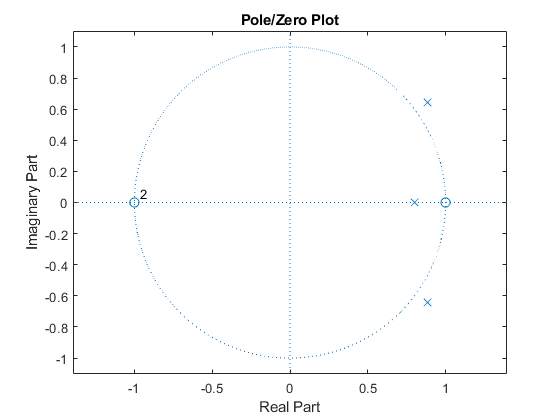

Orignal Gain: 32.3835
K value: 0.03088


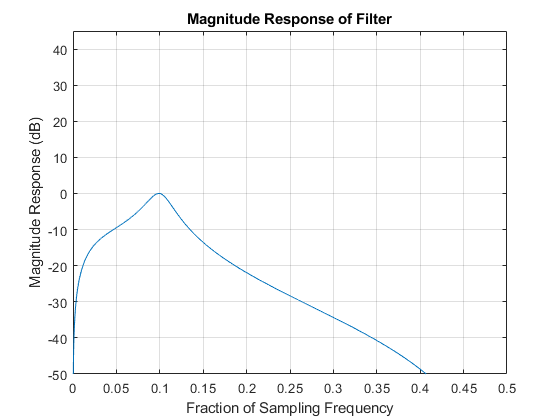

close all
clear
clc

coef(1,:,1) = [1,0,-1];
coef(1,:,2) = [1,1,0];
coef(2,:,1) = [1,-1.7725,1.2];
coef(2,:,2) = [1,-0.8,0];

DigitalPloter(coef,0)

# Page 4

close all
clear
clc

z = e ^ (2 pi j w)

z= exp(2*pi*1j*0.5)

z = -1.0000 + 0.0000i


%For Notch
CF = Digital.PreWarp(0.1);
num = [1,-2*cos(2*pi*Digital.UnWarp(CF)),1]

num =     1.0000   -1.6180    1.0000


%For BandPass
num = [1 0 -1];

%#8
Digital.PreWarp(0)

ans = 0

# Page 5

close all
clear
clc

mag = abs(freqz(1,[1,-0.5],1024));
max(abs(freqz(1,[1,-0.5],1024)))

ans = 2

mag(1024)

ans = 0.6667


Digital.UnWarp(sqrt(Digital.PreWarp(0.1)*Digital.PreWarp(0.25)))

ans = 0.1649

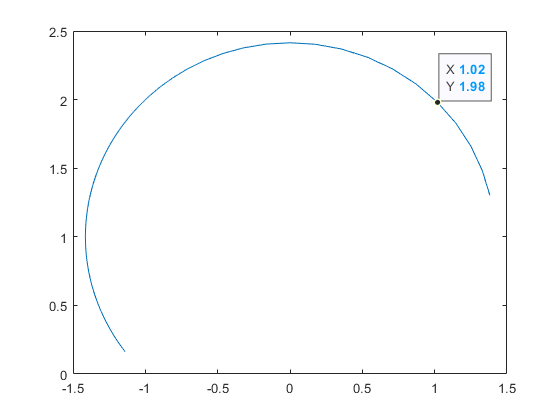


s = 1:0.1:20;
s = s.*exp(1j*(pi/4));
z = Digital.MyBLT(s);
plot(real(z),imag(z))